# Photoluminescence: data analysis

## Load data

clear;
RhoData = ParsePLdata('rhodamine', 'photonE');  % Rhodamine

Temps = 10:10:290;
RubyData = cell(numel(Temps),1);    % Ruby
for it = 1:numel(Temps)
    RubyData{it} = ParsePLdata('ruby', Temps(it), 'photonE');
end

RubyRoomData = ParsePLdata('rubyRtemp', 'photonE');

## Fit Rhodamine Data

%

## Fit Ruby Data to 4-level effective model (double lorentzian)

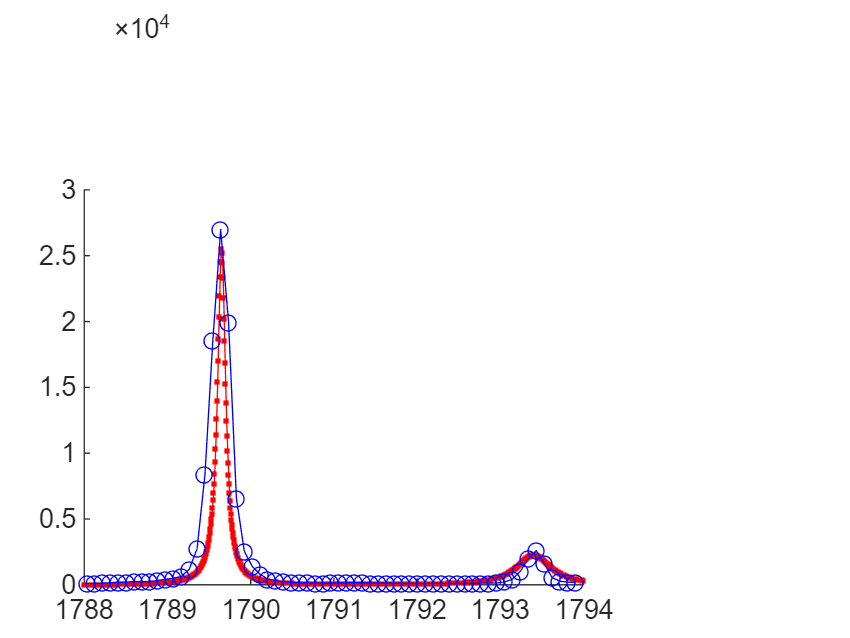

I0 = 1509


d_{20}/d_{10} = 5.455


Linewidths = [0.1182, 0.5012]


Delta = 3.753


E1 = 1790


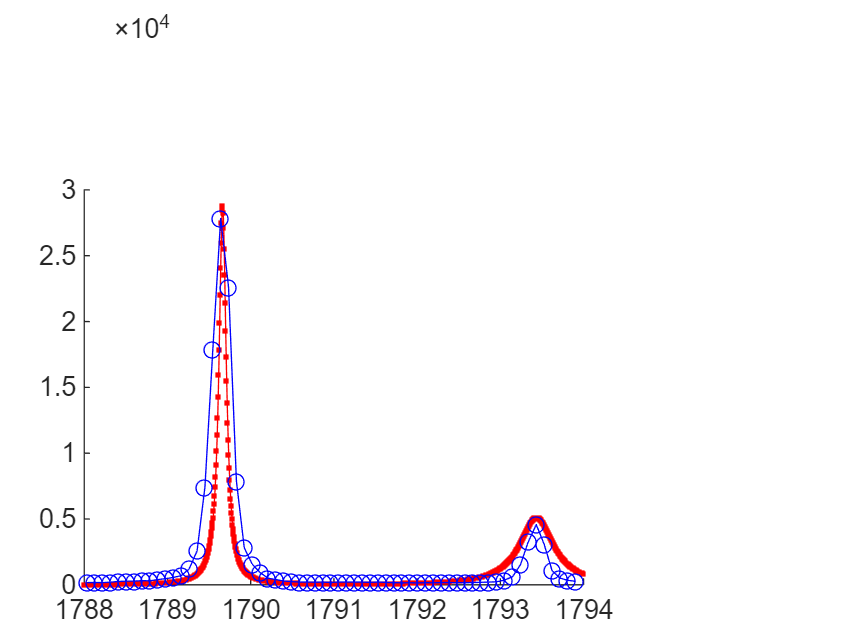

I0 = 1517


d_{20}/d_{10} = 2.754


Linewidths = [0.1055, 0.5012]


Delta = 3.775


E1 = 1790


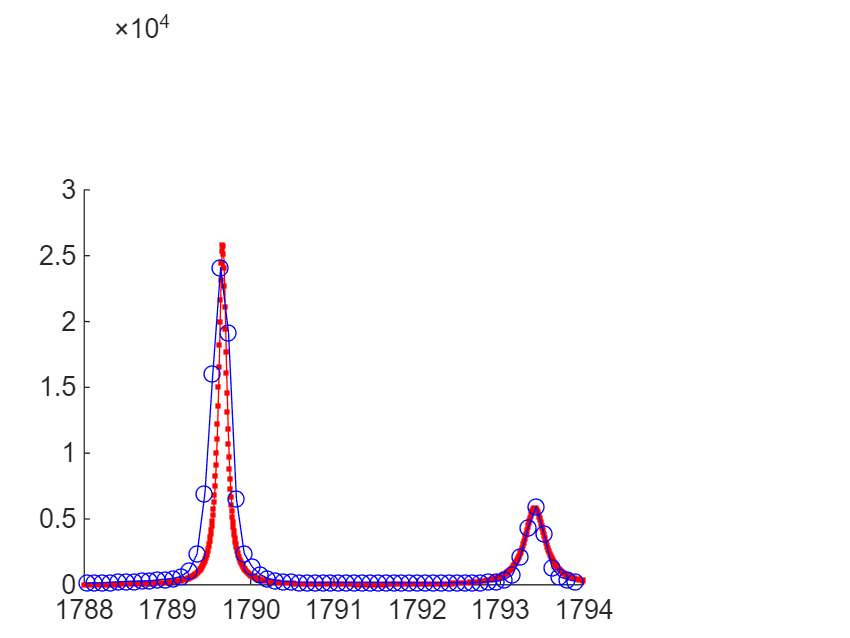

I0 = 1527


d_{20}/d_{10} = 1.559


Linewidths = [0.1182, 0.2961]


Delta = 3.754


E1 = 1790


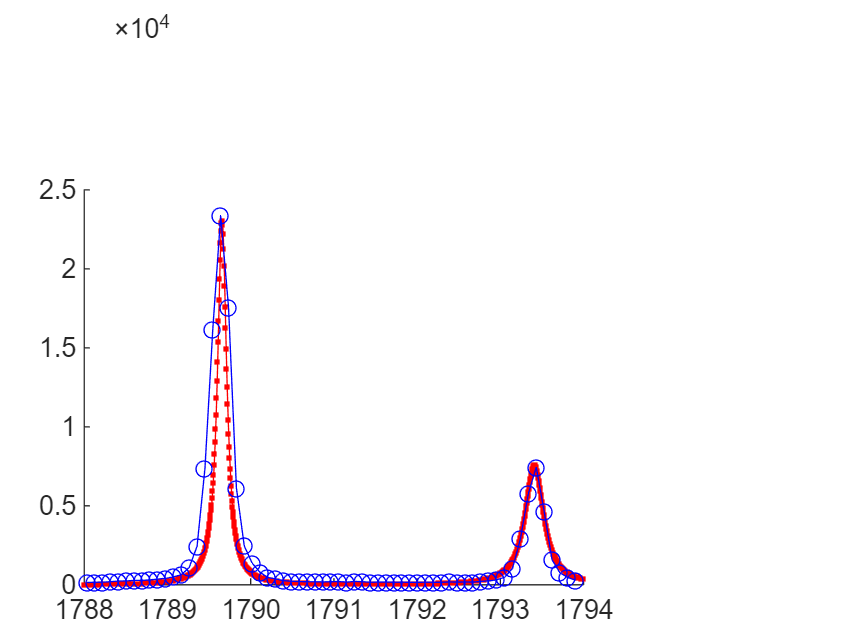

I0 = 1537


d_{20}/d_{10} = 1.409


Linewidths = [0.1334, 0.2702]


Delta = 3.756


E1 = 1790


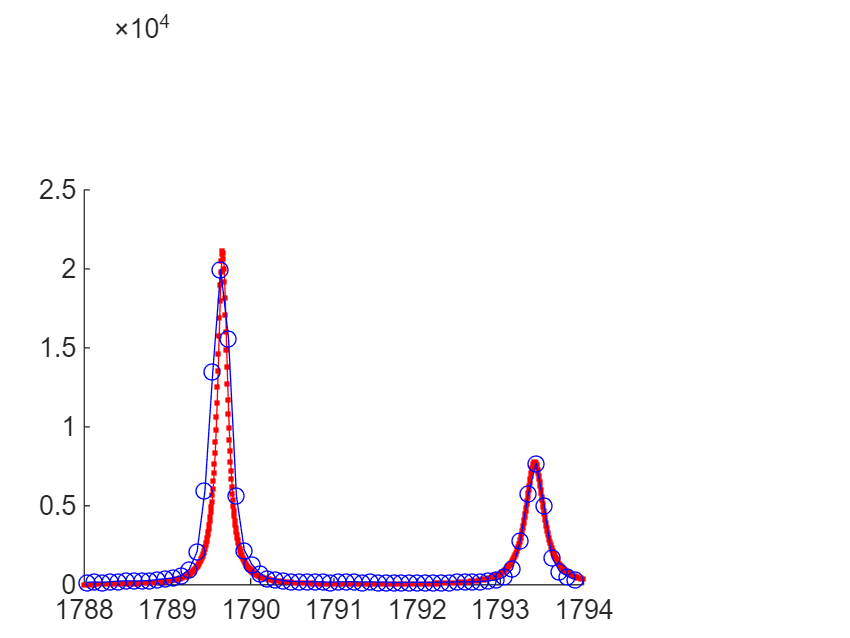

I0 = 1547


d_{20}/d_{10} = 1.268


Linewidths = [0.1464, 0.2659]


Delta = 3.753


E1 = 1790


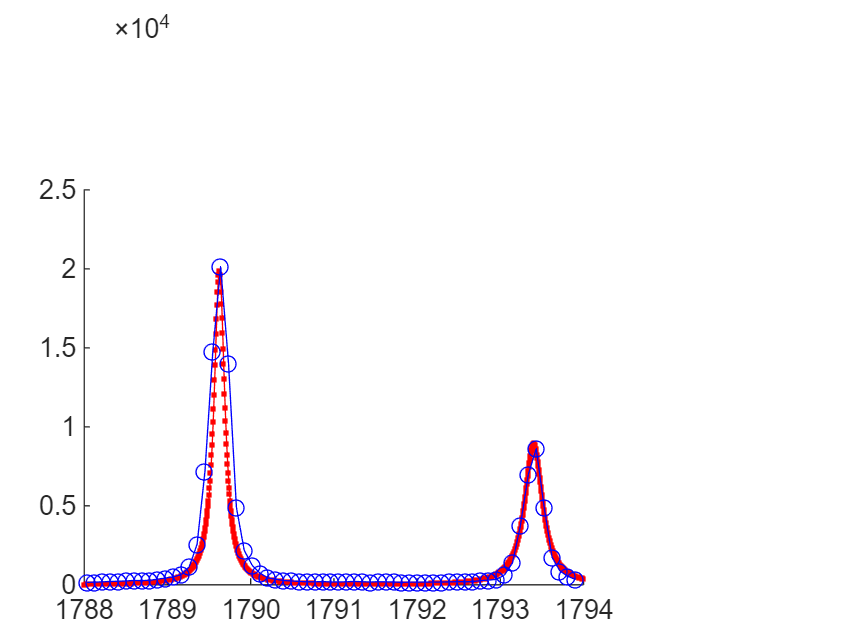

I0 = 1557


d_{20}/d_{10} = 1.245


Linewidths = [0.1566, 0.2589]


Delta = 3.779


E1 = 1790


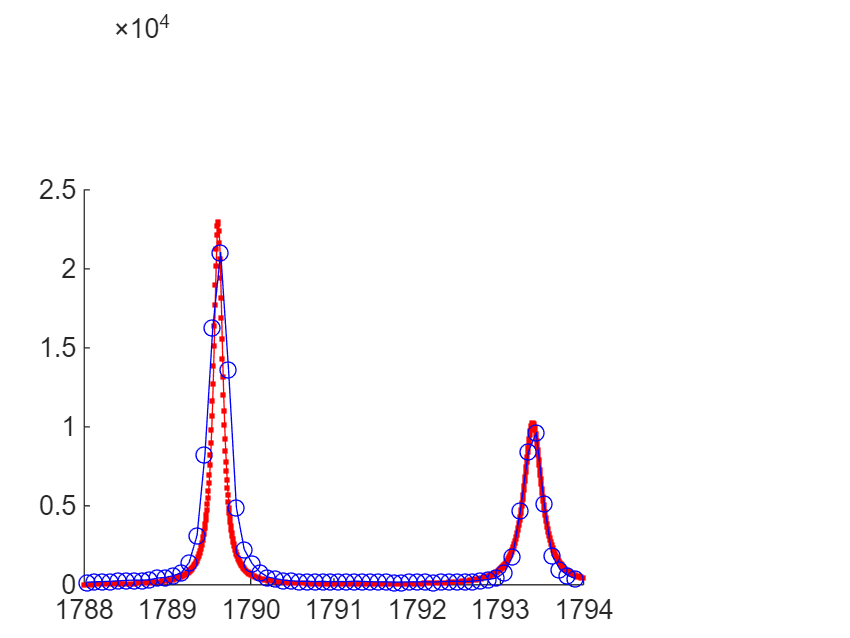

I0 = 1567


d_{20}/d_{10} = 1.262


Linewidths = [0.1364, 0.2587]


Delta = 3.784


E1 = 1790


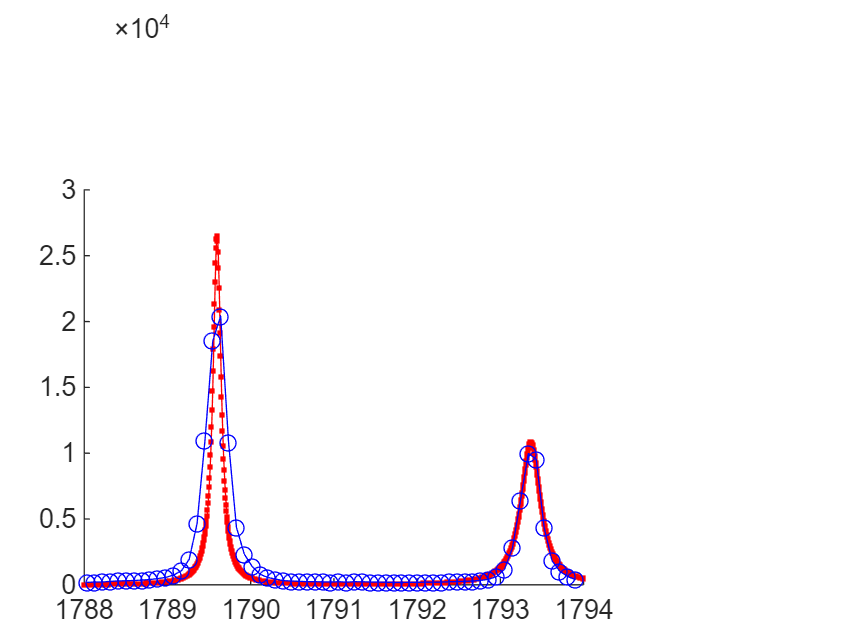

I0 = 1577


d_{20}/d_{10} = 1.29


Linewidths = [0.119, 0.2783]


Delta = 3.774


E1 = 1790


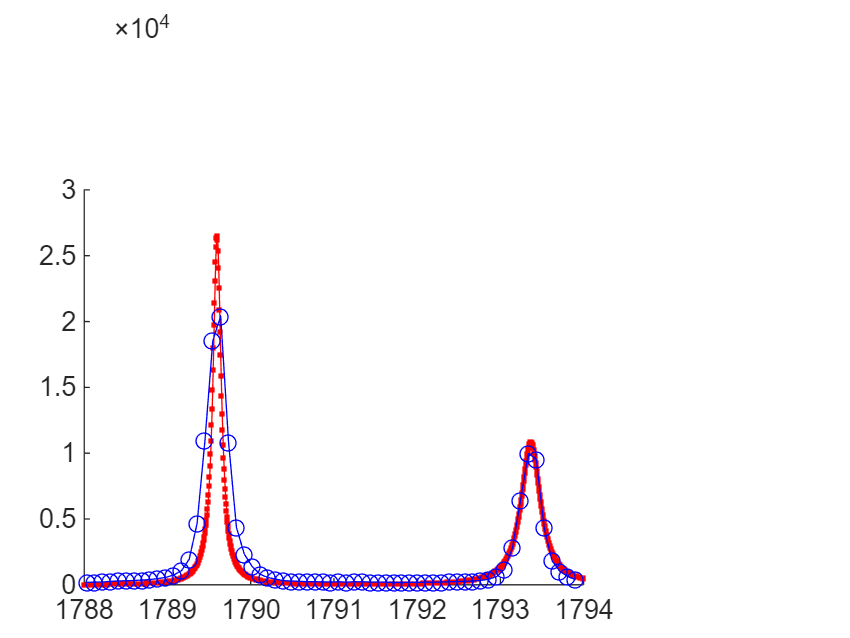

I0 = 1587


d_{20}/d_{10} = 1.247


Linewidths = [0.1196, 0.2782]


Delta = 3.774


E1 = 1790


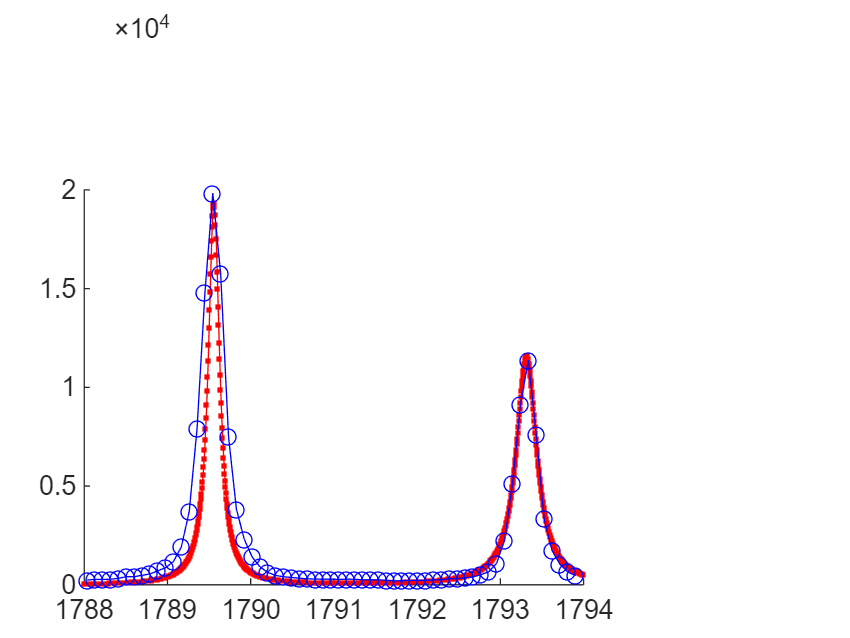

I0 = 1597


d_{20}/d_{10} = 1.288


Linewidths = [0.1652, 0.2958]


Delta = 3.759


E1 = 1790


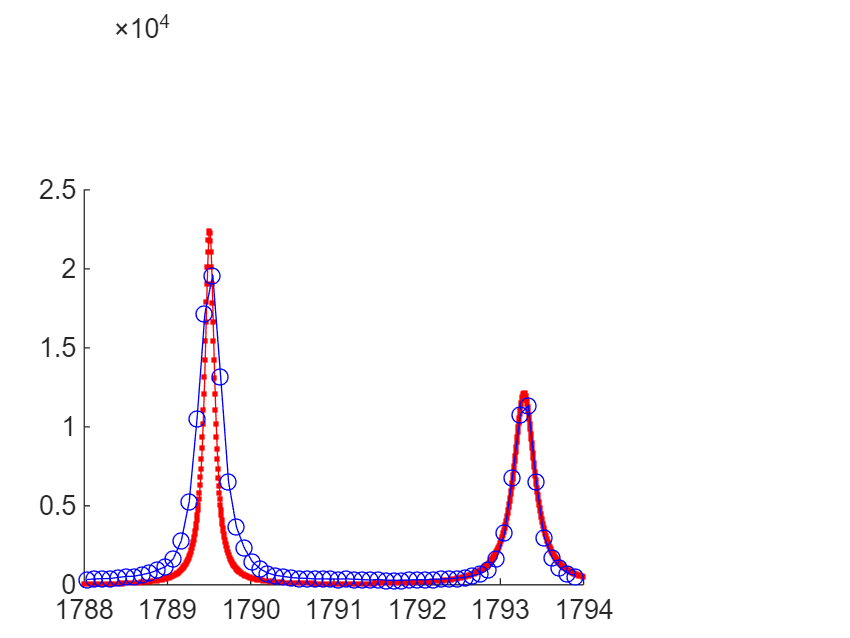

I0 = 1600


d_{20}/d_{10} = 1.316


Linewidths = [0.1427, 0.3053]


Delta = 3.783


E1 = 1790


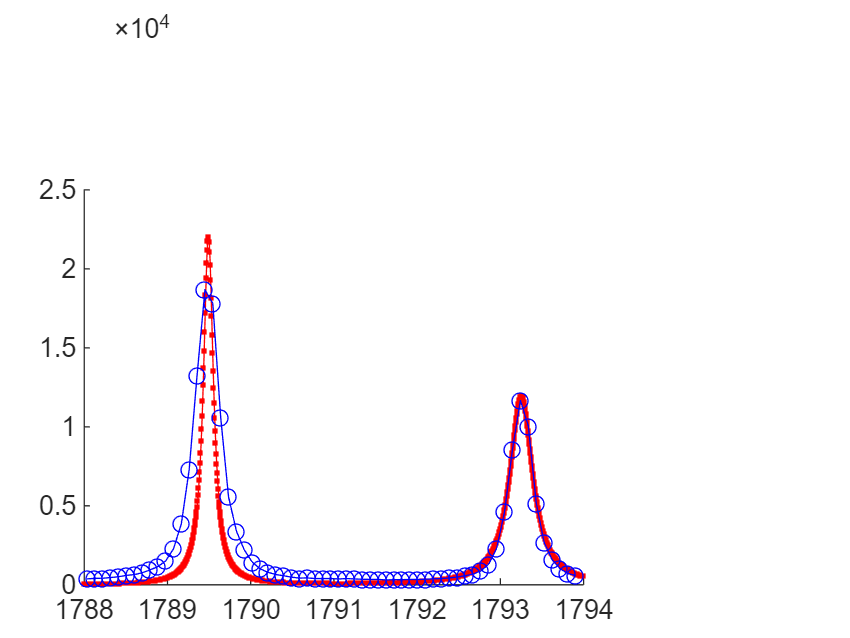

I0 = 1600


d_{20}/d_{10} = 1.332


Linewidths = [0.1451, 0.3292]


Delta = 3.763


E1 = 1789


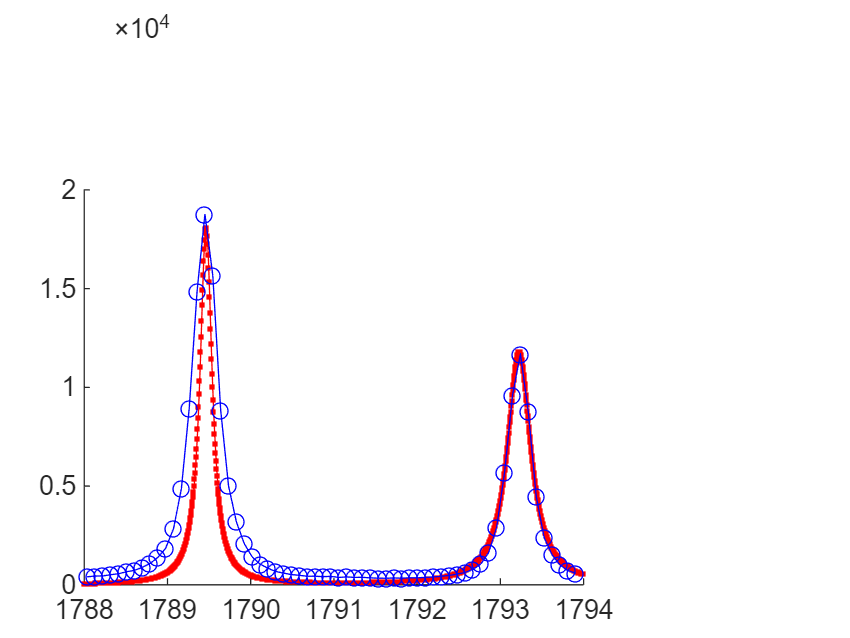

I0 = 1600


d_{20}/d_{10} = 1.324


Linewidths = [0.1769, 0.339]


Delta = 3.765


E1 = 1789


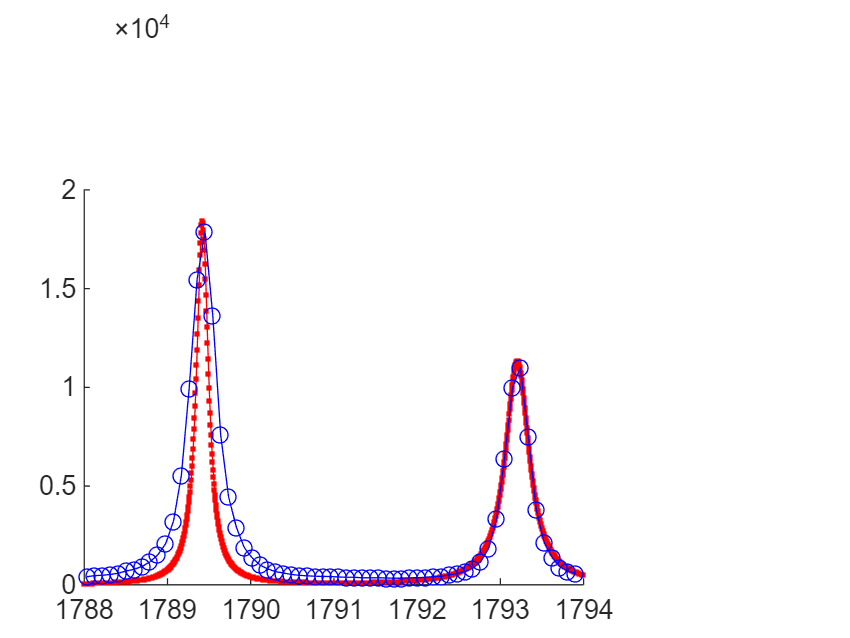

I0 = 1600


d_{20}/d_{10} = 1.295


Linewidths = [0.1734, 0.3446]


Delta = 3.786


E1 = 1789


I0 = 1600


d_{20}/d_{10} = 1.281


Linewidths = [0.1734, 0.3446]


Delta = 3.786


E1 = 1789


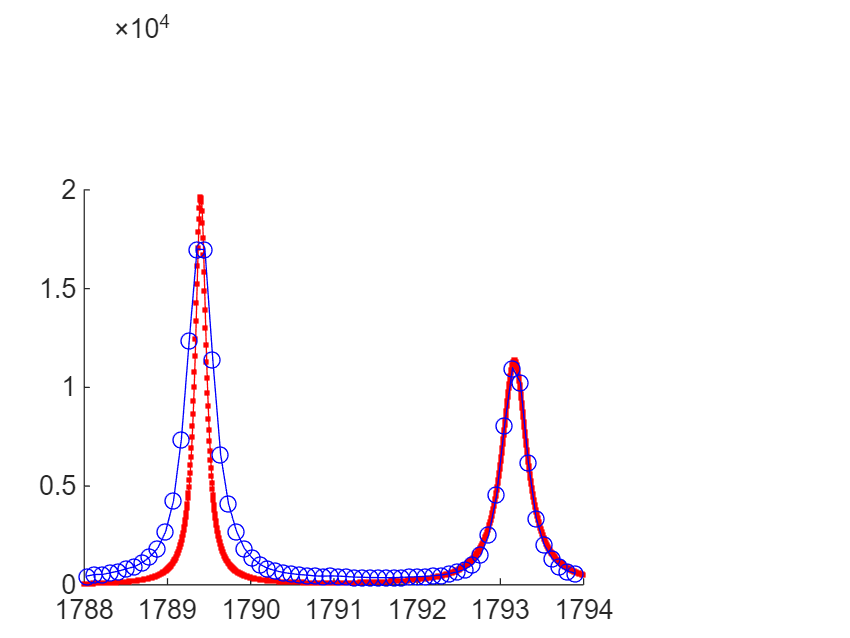

I0 = 1600


d_{20}/d_{10} = 1.305


Linewidths = [0.1628, 0.3641]


Delta = 3.772


E1 = 1789


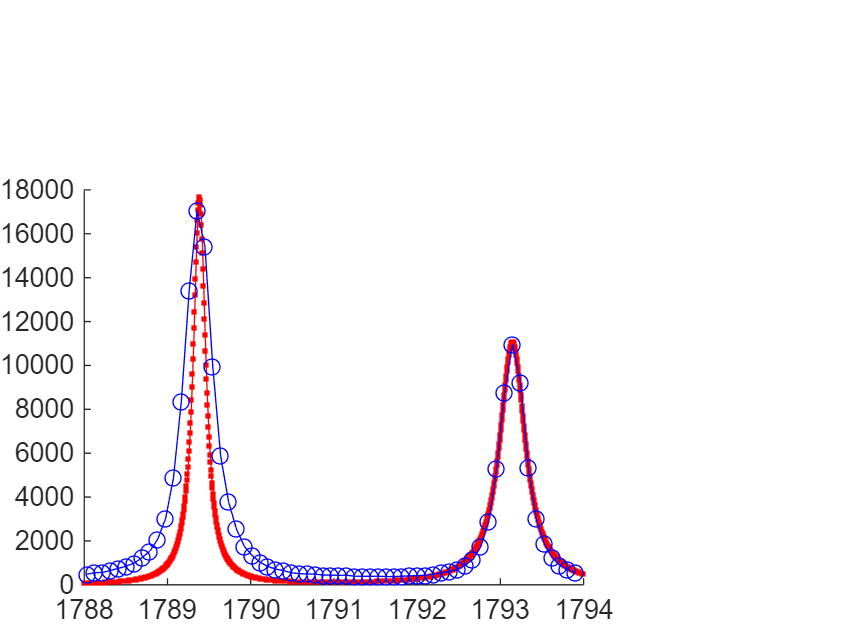

I0 = 1600


d_{20}/d_{10} = 1.294


Linewidths = [0.1812, 0.3734]


Delta = 3.764


E1 = 1789


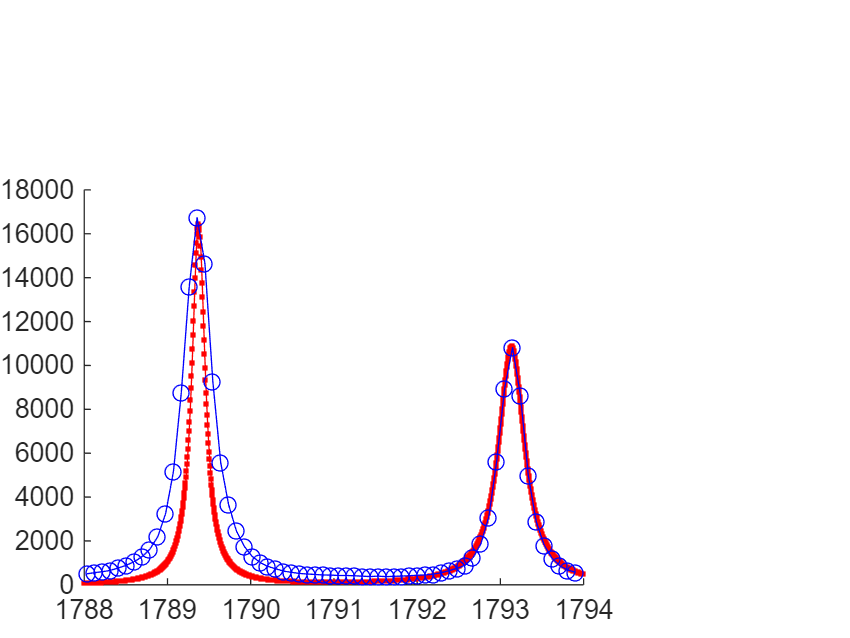

I0 = 1600


d_{20}/d_{10} = 1.279


Linewidths = [0.1945, 0.3772]


Delta = 3.765


E1 = 1789


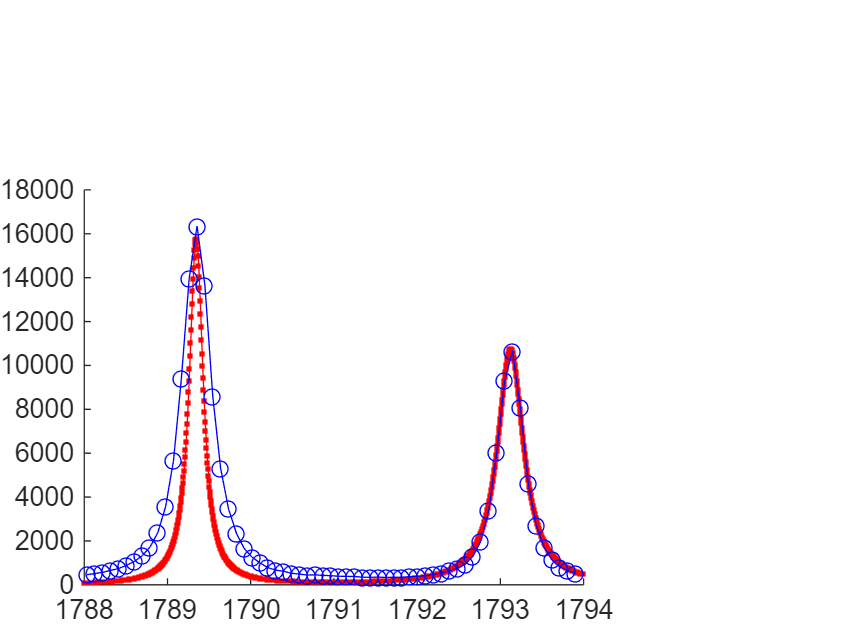

I0 = 1600


d_{20}/d_{10} = 1.269


Linewidths = [0.2031, 0.38]


Delta = 3.78


E1 = 1789


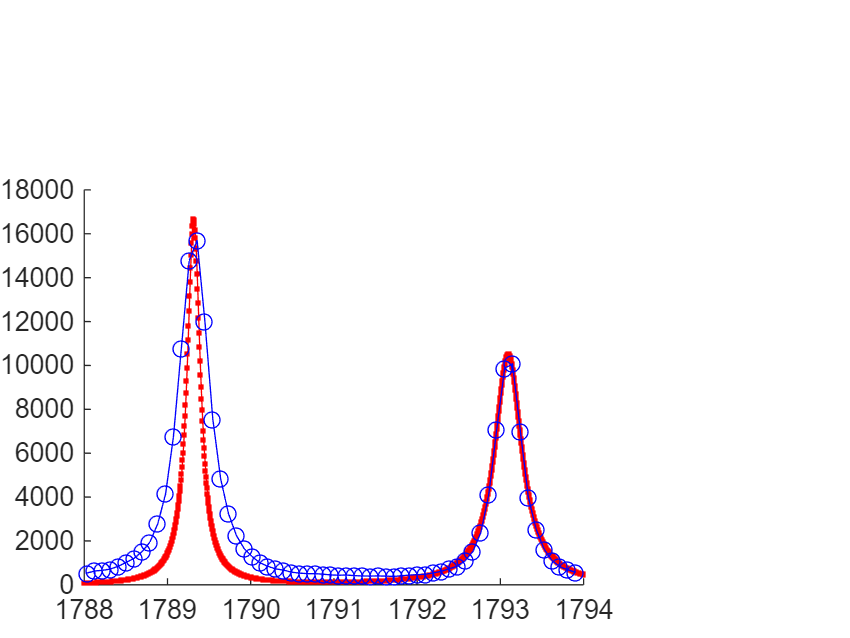

I0 = 1600


d_{20}/d_{10} = 1.273


Linewidths = [0.1921, 0.3955]


Delta = 3.782


E1 = 1789


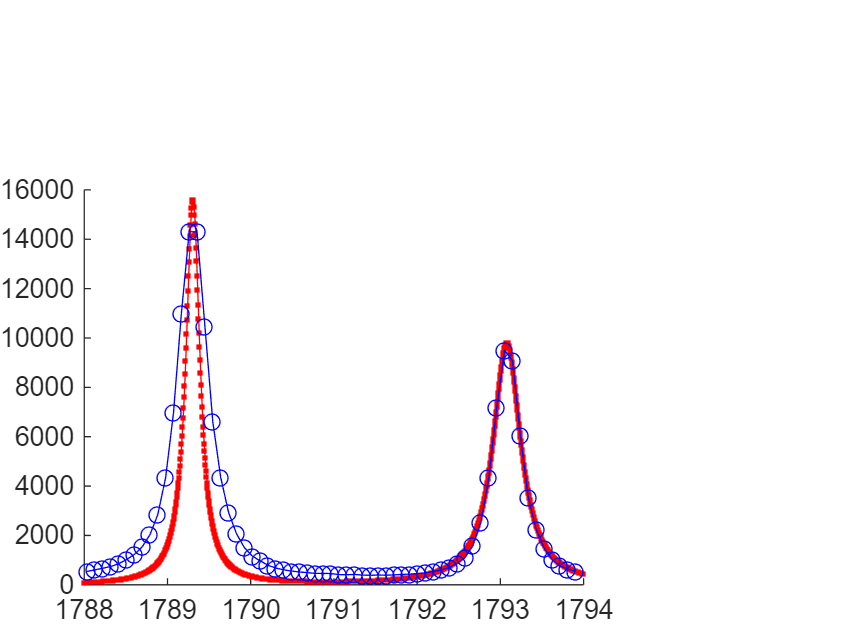

I0 = 1600


d_{20}/d_{10} = 1.234


Linewidths = [0.205, 0.4032]


Delta = 3.776


E1 = 1789


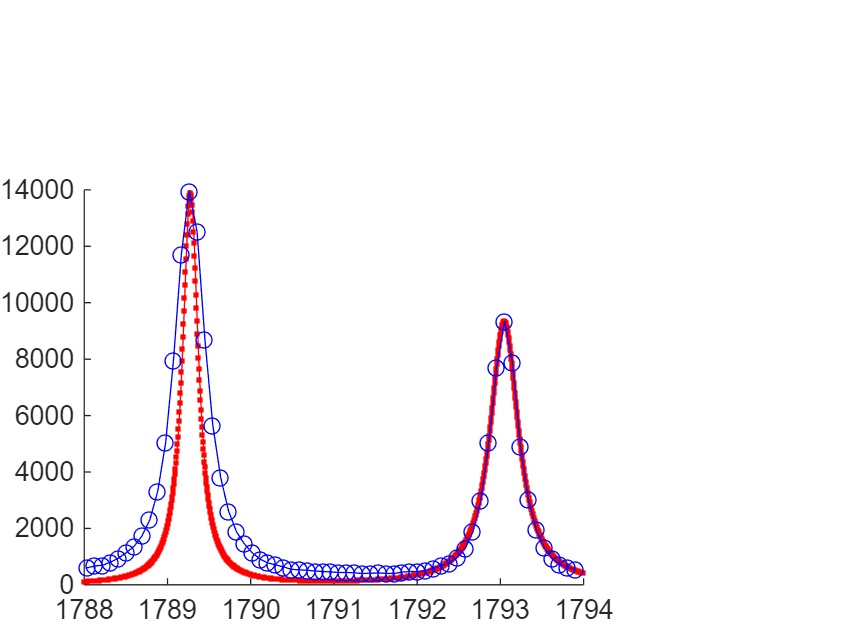

I0 = 1600


d_{20}/d_{10} = 1.213


Linewidths = [0.2305, 0.4133]


Delta = 3.775


E1 = 1789


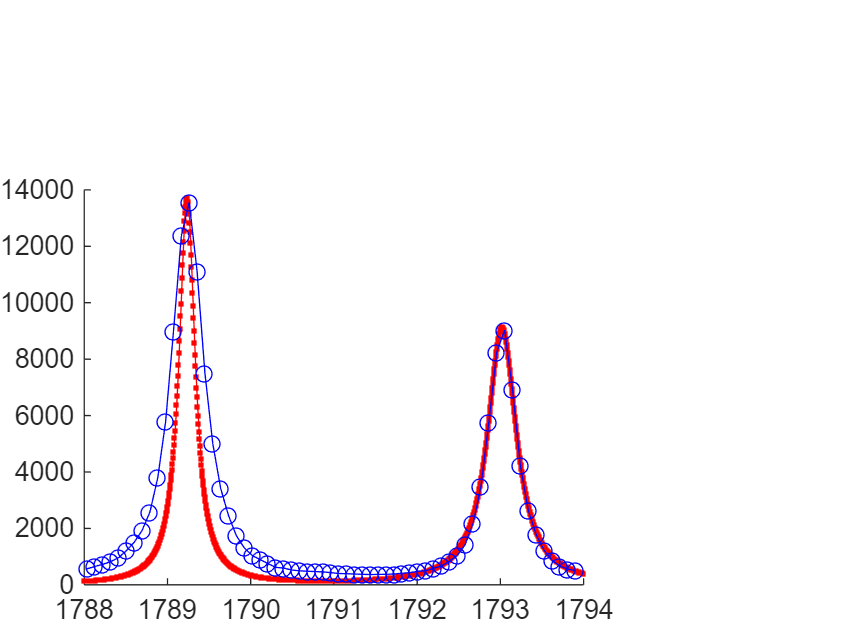

I0 = 1600


d_{20}/d_{10} = 1.205


Linewidths = [0.2336, 0.4203]


Delta = 3.787


E1 = 1789


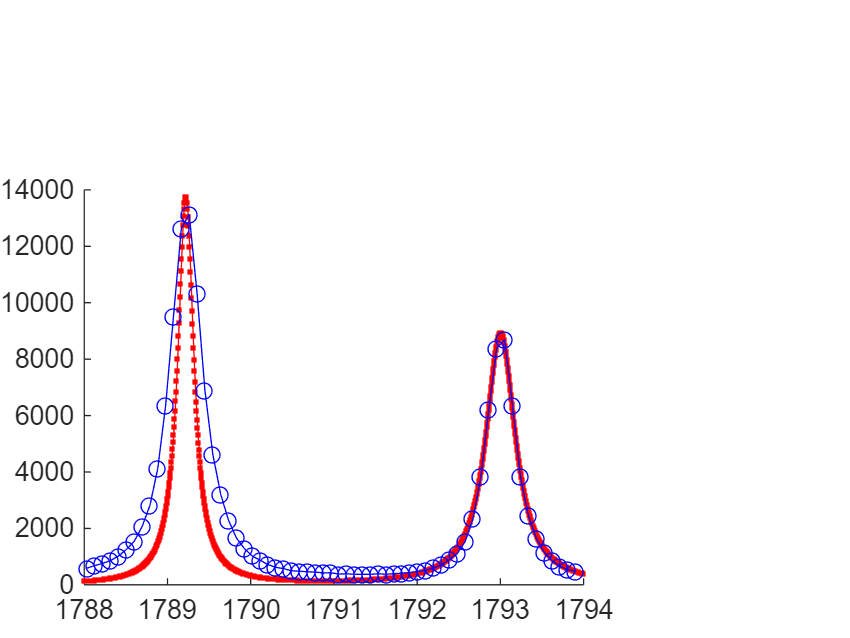

I0 = 1600


d_{20}/d_{10} = 1.2


Linewidths = [0.2327, 0.4291]


Delta = 3.785


E1 = 1789


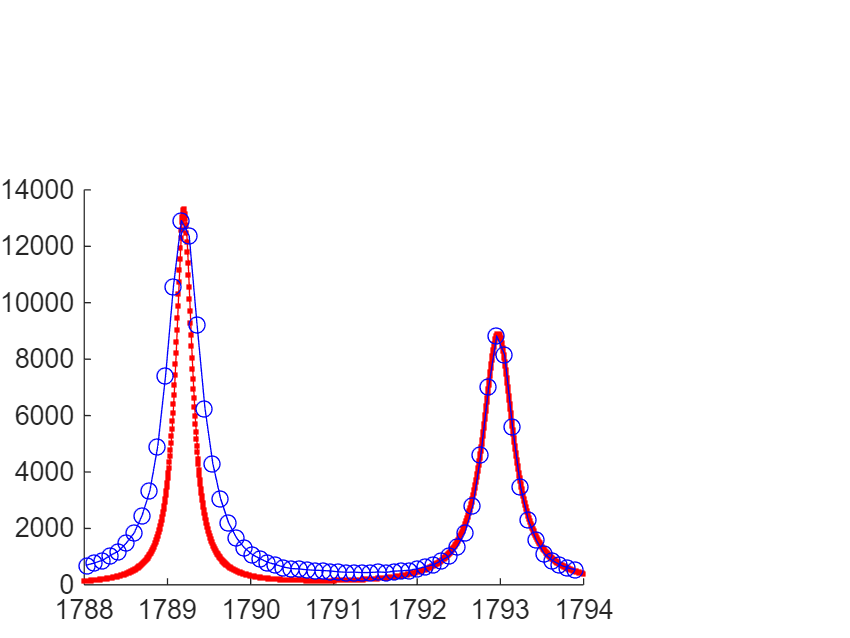

I0 = 1600


d_{20}/d_{10} = 1.216


Linewidths = [0.2407, 0.4458]


Delta = 3.777


E1 = 1789


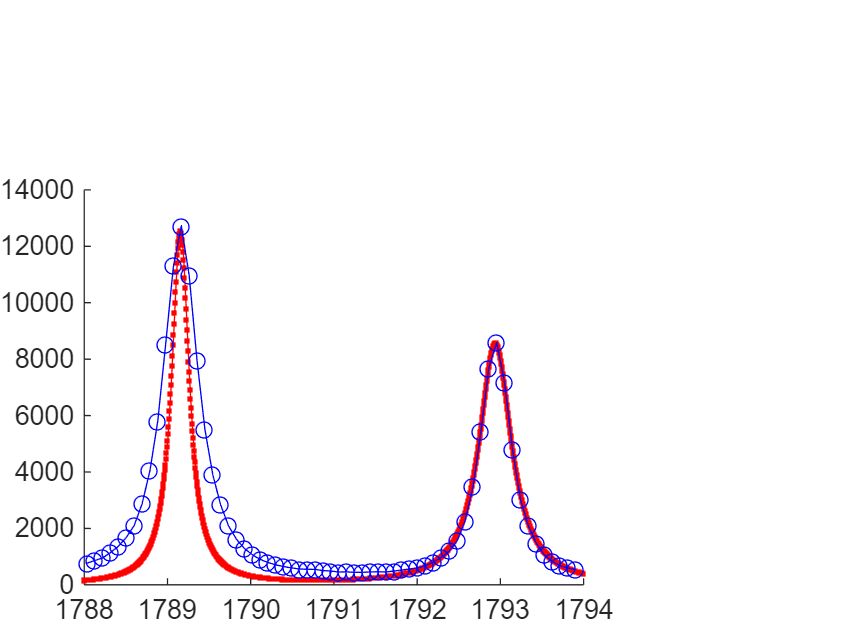

I0 = 1600


d_{20}/d_{10} = 1.222


Linewidths = [0.2557, 0.4707]


Delta = 3.785


E1 = 1789


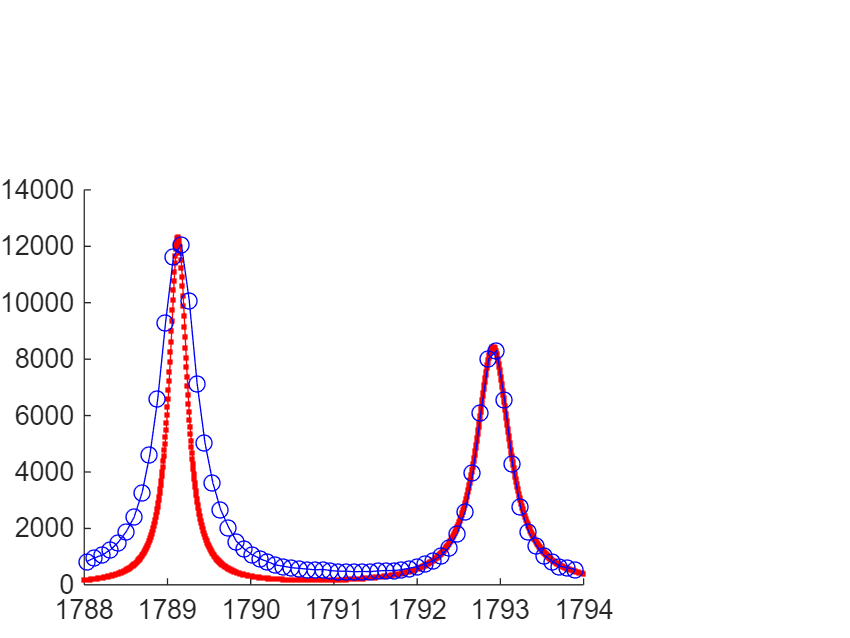

I0 = 1600


d_{20}/d_{10} = 1.228


Linewidths = [0.2597, 0.4857]


Delta = 3.787


E1 = 1789


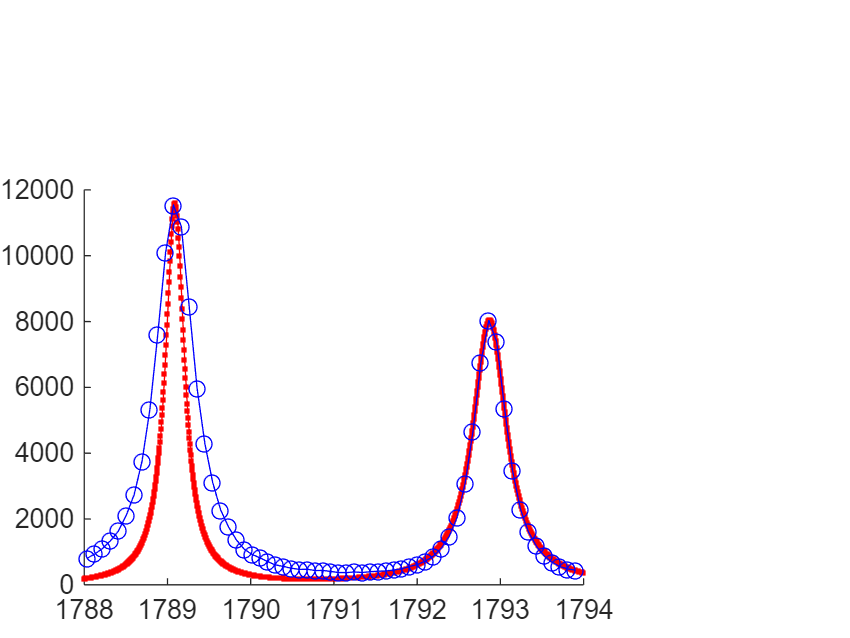

I0 = 1600


d_{20}/d_{10} = 1.206


Linewidths = [0.2765, 0.4945]


Delta = 3.784


E1 = 1789


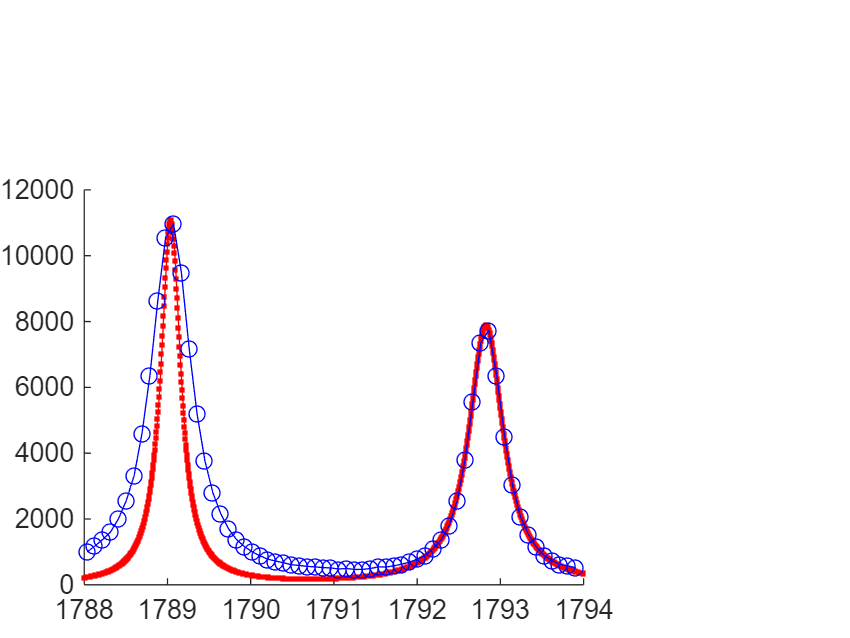

I0 = 1600


d_{20}/d_{10} = 1.199


Linewidths = [0.2894, 0.5012]


Delta = 3.791


E1 = 1789


Erange = [1788, 1794];
Energy = linspace(Erange(1), Erange(2), 1000);

FitParams = [1500, 3, -0.7, -0.7, 3.6, 1790];

for Dnum = 1:29
    T = 10*Dnum;
    
    Idx = RubyData{Dnum}(:,1) > Erange(1) & RubyData{Dnum}(:,1) < Erange(2);
    E_data = RubyData{Dnum}(Idx,1);
    I_data = RubyData{Dnum}(Idx,2);
    
    LowerBound = [1400, 1e-1, -2, -2, 1, 1780];
    UpperBound = [1600, 1e1, -0.3, -0.3, 4, 1800];
    Thres = I_data(fix(numel(E_data)/2));
    loss_func = @(y_hat, y_data) mean(((y_hat - y_data).^2) .* (y_data>Thres | (y_data<Thres & y_hat>Thres)) .* abs(max(y_data,y_hat)));
    
    options.lb = LowerBound;
    options.ub = UpperBound;
    options.loss_type = loss_func;
    
    Params0 = FitParams;
    FitModel = @(Params, Energies) RubySpec(Params(1), Params(2), [power(10, Params(3)), power(10, Params(4))], Params(5), Params(6), T, Energies);
    [FitParams, ~] = Adam_curve_fit(FitModel, E_data, I_data, Params0, options);
    
    I0 = FitParams(1);
    TransAmpR = FitParams(2);
    Linewidth = [power(10, FitParams(3)), power(10, FitParams(4))];
    Delta = FitParams(5);
    E1 = FitParams(6);
    
    figure;
    hold on;
    I_fit = RubySpec(I0, TransAmpR, Linewidth, Delta, E1, T, Energy);
    plot(Energy, I_fit, '.-', 'color', 'red');
    plot(E_data, I_data, 'o-', 'color', 'blue');
    hold off;
    
    disp(['I0 = ', sprintf('%.4g', I0)]);
    disp(['d_{20}/d_{10} = ', sprintf('%.4g', TransAmpR)]);
    disp(['Linewidths = [', sprintf('%.4g', Linewidth(1)), ', ', sprintf('%.4g', Linewidth(2)) ']']);
    disp(['Delta = ', sprintf('%.4g', Delta)]);
    disp(['E1 = ', sprintf('%.4g', E1)]);
end